# Introduction to PID controller - Intitutive Way

close all;

## Second order Transfer function

Consider any second order transfer function, for example:

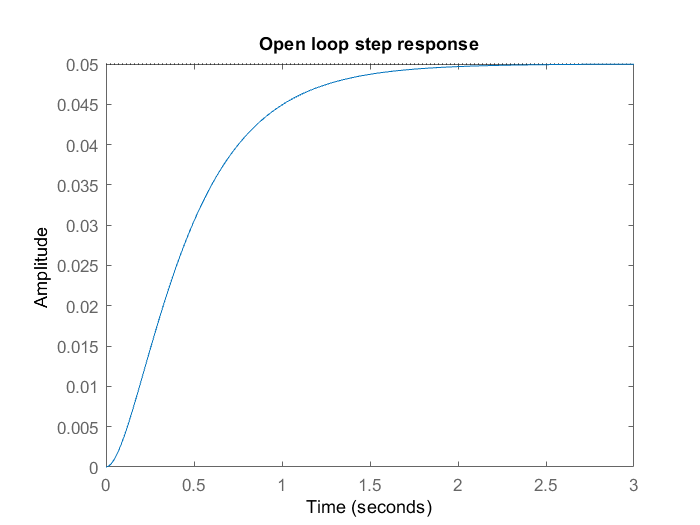

G=tf(1,[1 10 20]); % 

%-- Plot the open loop step response
figure;
step(G); title('Open loop step response');

% Lets say we want to track reference of 1. We will design P, PI, PD, and
% PID controllers to achieve this

## Design of a Proportional Controller

Lets assume a value of Kp

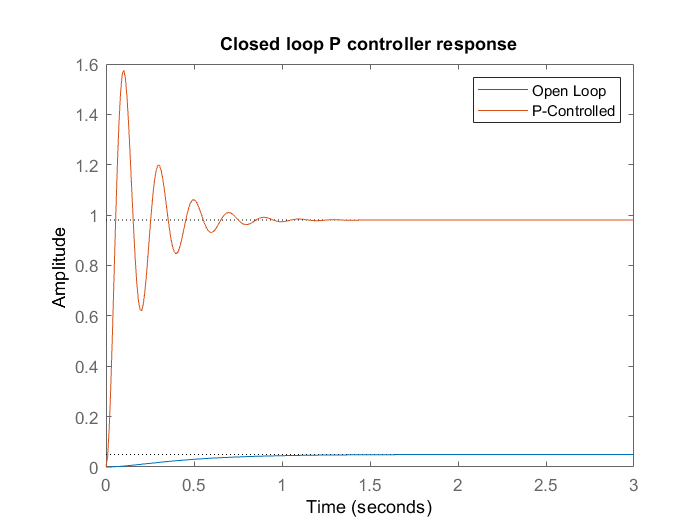

Kp = 1000; Kd =0; Ki = 0;
Con = pid(Kp,Ki,Kd); % The pid command can be used to design the PID conroller
P = feedback(Con*G,1);% feedback command places the controller structure.
%--- Plot the response for P controller
figure;
step(G); hold on; step (P); 
legend('Open Loop','P-Controlled'); 
title('Closed loop P controller response')

## Design of a Proportional-Derivative Controller

Lets assume a value of Kp and Kd

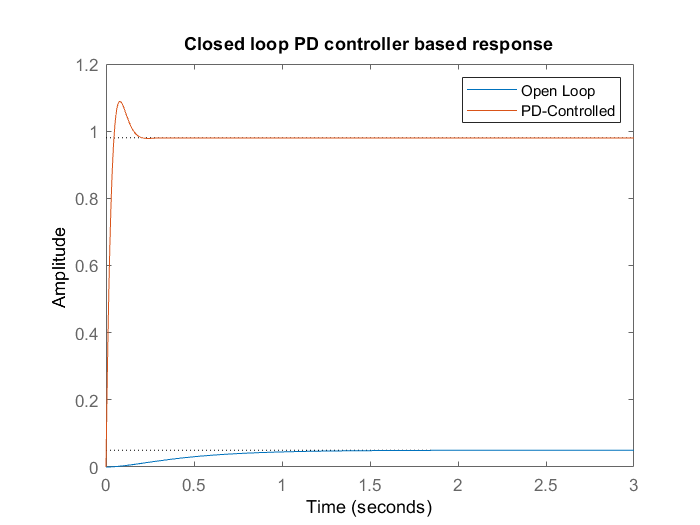

Kp = 1000; Kd = 40; Ki = 0;
Con = pid(Kp,Ki,Kd); % The pid command can be used to design the PID conroller
PD = feedback(Con*G,1);% feedback command places the controller structure.
%--- Plot the response for P controller
figure;
step(G); hold on; step (PD);
legend('Open Loop','PD-Controlled'); 
title('Closed loop PD controller based response');

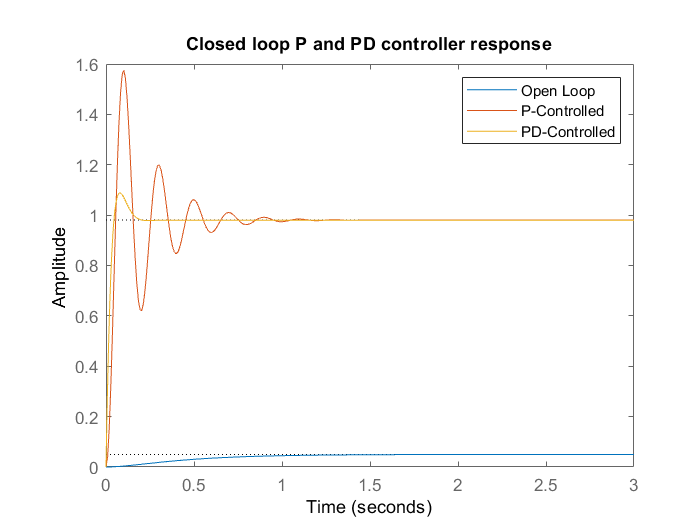

figure; 
step(G); hold on; step(P); step (PD);
legend('Open Loop','P-Controlled','PD-Controlled'); 
title('Closed loop P and PD controller response');

## Design of a Proportional-Integral Controller

Lets assume a value of Kp and Kd

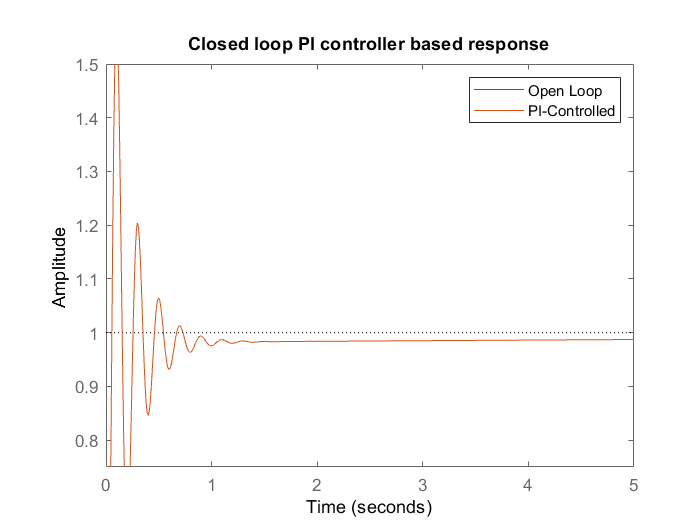

Kp = 1000; Kd = 0; Ki =80;
Con = pid(Kp,Ki,Kd); % The pid command can be used to design the PID conroller
PI = feedback(Con*G,1);% feedback command places the controller structure.
%--- Plot the response for P controller
figure;
step(G); hold on; step (PI);axis([0 5 0.75 1.5] )
legend('Open Loop','PI-Controlled'); 
title('Closed loop PI controller based response');

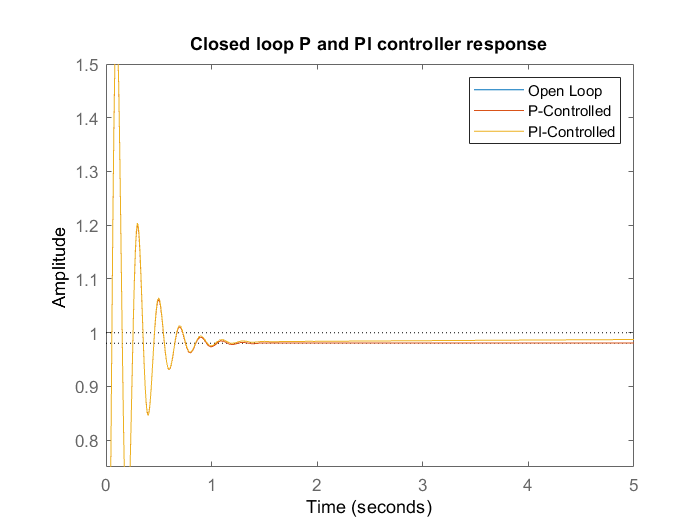

figure; 
step(G); hold on; step(P); step (PI);axis([0 5 0.75 1.5] )
legend('Open Loop','P-Controlled','PI-Controlled'); 
title('Closed loop P and PI controller response');

## Design of a Proportional-Integral-Derivative Controller

Lets assume a value of Kp and Kd

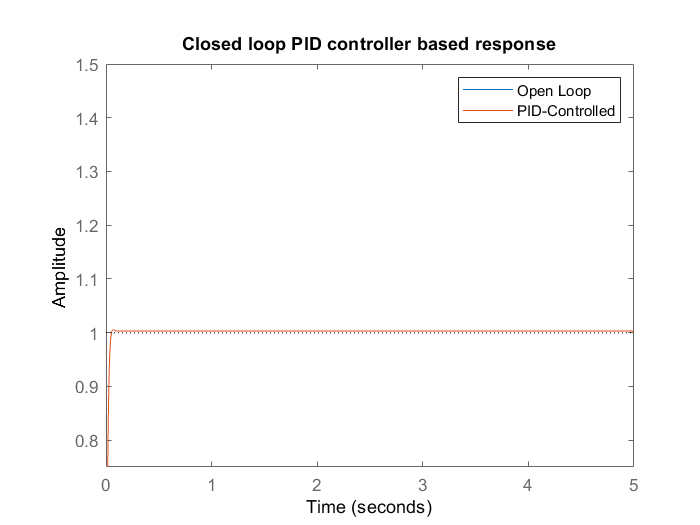

Kp = 1000; Kd = 80; Ki =100;
Con = pid(Kp,Ki,Kd); % The pid command can be used to design the PID conroller
PID = feedback(Con*G,1);% feedback command places the controller structure.
%--- Plot the response for P controller
figure;
step(G); hold on; step (PID);axis([0 5 0.75 1.5] )
legend('Open Loop','PID-Controlled'); 
title('Closed loop PID controller based response');

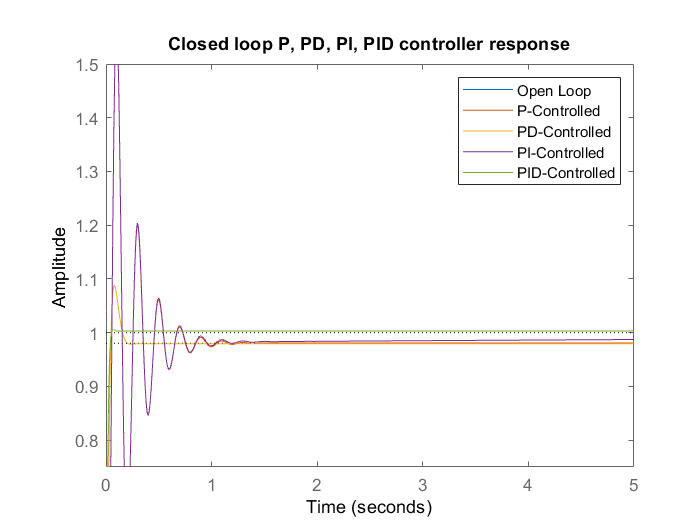

figure; 
step(G); hold on; step(P);step (PD); step (PI);step (PID);axis([0 5 0.75 1.5] )
legend('Open Loop','P-Controlled','PD-Controlled','PI-Controlled','PID-Controlled'); 
title('Closed loop P, PD, PI, PID controller response');